# Check response autocorrelations

Load data:

clear;
clc;

data_struct = loadData()

data_struct =   Map with properties:

        Count: 77
      KeyType: char
    ValueType: any


subjects = {'01RoYi','02XiHo','03JaVe','04NiSi','05PeYa','06KuSh',...
    '07AnWo','08LiBa', '09KeVa', '10MaIv', '11YaSi', '12JaGu',...
    '13ChSc','14SaMc','15ChFi', '16JoDa', '17IvSi','18LuHe','19ElBo','20MiLa',...
    '21ShZh', '22PeYe', '23InMa', '24WePi', '25AyLe', '26DeCa', '27LoLi', ...
    '28WiTa', '29CrRa','30OrAl','31FeKu','32EeXu','33KaBh'};


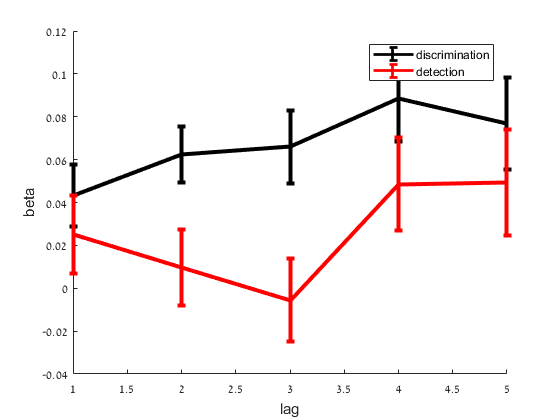

Dis_Coeffs = [];
Det_Coeffs = [];

for s=1:length(subjects)
    subj = data_struct(subjects{s});
    DisMat = [];
    DetMat = [];
    for i = 1:6
        DisVec = [];
        DetVec = [];
        for block = 0:40:160
            DisVec = [DisVec; subj.DisResp([i+block:i+block+29])];
            DetVec = [DetVec; subj.DetResp([i+block:i+block+29])];
        end
        DisMat = [DisMat DisVec];
        DetMat = [DetMat DetVec];
    end
    
    Dis_B = corr(DisMat(:,1:5), DisMat(:,6)+1);
    Det_B = corr(DetMat(:,1:5), DetMat(:,6)+1);
    Dis_Coeffs = [Dis_Coeffs Dis_B(1:5)];
    Det_Coeffs = [Det_Coeffs Det_B(1:5)];
end

    figure
    hold on
    errorbar(mean(Dis_Coeffs'),std(Dis_Coeffs')/sqrt(length(subjects)),'k','LineWidth',3);
    errorbar(mean(Det_Coeffs'),std(Det_Coeffs')/sqrt(length(subjects)),'r','LineWidth',3);
    legend('discrimination','detection')
    xlabel('lag');
    ylabel('beta')